close all; clearvars; clc;

## 1. Generate datasets X1 and X2

M=2; %Number class
m=[zeros(5,1) ones(5,1)];
S(:,:,1)=[0.8 0.2 0.1 0.05 0.01;
          0.2 0.7 0.1 0.03 0.02;
          0.1 0.1 0.8 0.02 0.01;
          0.05 0.03 0.02 0.9 0.01;
          0.01 0.02 0.01 0.01 0.8];
S(:,:,2)=[0.9 0.1 0.05 0.02 0.01;
          0.1 0.8 0.1 0.02 0.02;
          0.05 0.1 0.7 0.02 0.01;
          0.02 0.02 0.02 0.6 0.02;
          0.01 0.02 0.01 0.02 0.7];
P=[1/2 1/2 ]'; N1=100;
randn('state',0);
[X1,y1]=generate_gauss_classes(m,S,P,N1);
N2=10000;
randn('state',100);
[X2,y2]=generate_gauss_classes(m,S,P,N2);

%%2.  Use function Gaussian_ML_estimate to compute the ML_estimate of the mean and

## variance per feature for each class (using set X1)

for i=1:5
    [m1_hat(i), S1_hat(i)]=Gaussian_ML_estimate(X1(i,find(y1==1)));
end
m1_hat=m1_hat'; S1_hat=S1_hat';
for i=1:5
    [m2_hat(i), S2_hat(i)]=Gaussian_ML_estimate(X1(i,find(y1==2)));
end
m2_hat=m2_hat'; S2_hat=S2_hat';

## 3. Classify each point in X2 according to the naive Bayes classification scheme

for i=1:5
    perFeature1(i,:)=normpdf(X2(i,:),m1_hat(i),sqrt(S1_hat(i)));
    perFeature2(i,:)=normpdf(X2(i,:),m2_hat(i),sqrt(S2_hat(i)));
end
naive_probs1=prod(perFeature1);
naive_probs2=prod(perFeature2);
classified=ones(1,length(X2));
classified(find(naive_probs1<naive_probs2))=2;

## Compute the confusion matrix

Index set for plotconfusion Label Tests Data Set

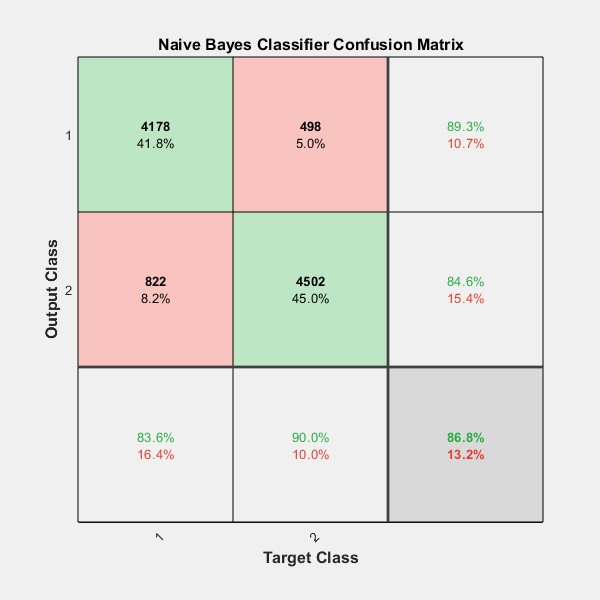

ind_t1=find(y2==1);ind_t2=find(y2==2); 
Targets=zeros(M,N1);
Targets(1,ind_t1)=1; Targets(2,ind_t2)=1; 

% Label ML estimate + Bayes Classifier 
ind_1=find(classified==1); ind_2=find(classified==2); 
Outputs=zeros(M,N2);
Outputs(1,ind_1)=1; Outputs(2,ind_2)=1; 
% Plot Confusion
 plotconfusion(Targets,Outputs,'Naive Bayes Classifier')

## 4. Compute the maximum likelihood estimates of the "unknown” mean values and covariance

## matrices, m1, m2, S1 and S2, based on X1

[m1_ML, S1_ML]=Gaussian_ML_estimate(X1(:,find(y1==1)));
[m2_ML, S2_ML]=Gaussian_ML_estimate(X1(:,find(y1==2)));

## 5. Classify the data vectors of X2 using the Bayesian classifier, which is based on the ML

## estimates of the respective parameters, type

m_ML(:,1)=m1_ML;
m_ML(:,2)=m2_ML;
S_ML(:,:,1)=S1_ML;
S_ML(:,:,2)=S2_ML;
P=[1/2 1/2];
z=bayes_classifier(m_ML,S_ML,P,X2);

## Compute the confusion matrix

Index set for plotconfusion Label Tests Data Set

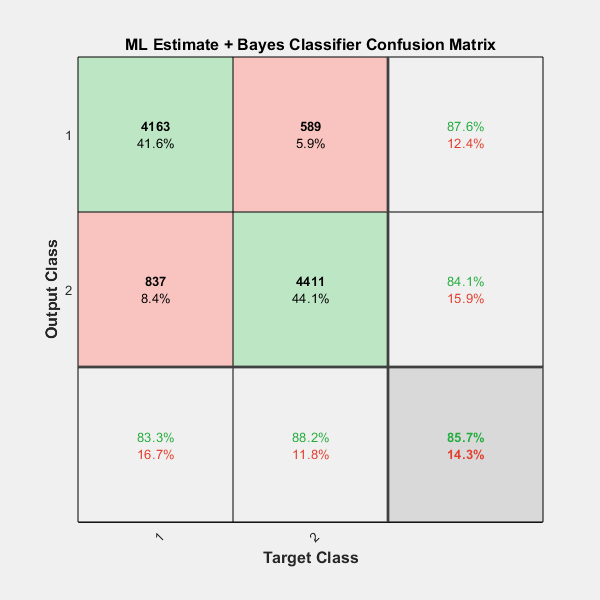

ind_t1=find(y2==1);ind_t2=find(y2==2); 
Targets=zeros(M,N1);
Targets(1,ind_t1)=1; Targets(2,ind_t2)=1; 

% Label ML estimate + Bayes Classifier 
ind_1=find(z==1); ind_2=find(z==2); 
Outputs=zeros(M,N2);
Outputs(1,ind_1)=1; Outputs(2,ind_2)=1; 
% Plot Confusion
figure; plotconfusion(Targets,Outputs,'ML Estimate + Bayes Classifier')